# Module 5, Lesson 1: Finding Peaks

This Live Script demonstrates the analysis from the video "Finding Peaks".

## Load the data

Load the two files with speech recordings: "FemaleSpeech-16-4-mono-20secs.wav" and "MaleSpeech-16-4-mono-20secs.wav". These signals both contain 20 seconds of speech, and as the name implies, from speakers with different sexes. 

Load the female speech data with the function `audioread`. This will return two variables: the signal and the sample rate. You can then create a time table from these variables

netFolder = downloadSoundFiles; % Downloads and unzips the required sample files from mathworks.com

[femaleData,femaleSampleRate] = audioread(fullfile(netFolder,"FemaleSpeech-16-4-mono-20secs.wav"));
femaleSpeech = timetable(femaleData, ...
    'SampleRate',femaleSampleRate, ...
    'VariableNames',"Data")

femaleSpeech = 80000×1 timetable
       Time           Data    
    ___________    ___________

    0 sec           -0.0015259
    0.00025 sec     -0.0040283
    0.0005 sec      -0.0066528
    0.00075 sec     -0.0062561
    0.001 sec       -0.0026245
    0.00125 sec     -0.0037231
    0.0015 sec      -0.0030823
    0.00175 sec     -0.0037537
    0.002 sec       -0.0055237
    0.00225 sec     -0.0044861
    0.0025 sec      -0.0027466
    0.00275 sec    -0.00073242
    0.003 sec       0.00054932
    0.00325 sec     0.00073242
    0.0035 sec       0.0021362
    0.00375 sec    -9.1553e-05


Repeat for the male speech recording

[maleData,maleSampleRate] = audioread(fullfile(netFolder,"MaleSpeech-16-4-mono-20secs.wav"));
maleSpeech = timetable(maleData, ...
    'SampleRate',maleSampleRate, ...
    'VariableNames',"Data")

maleSpeech = 80000×1 timetable
       Time          Data   
    ___________    _________

    0 sec          -0.020782
    0.00025 sec     0.018158
    0.0005 sec     -0.015259
    0.00075 sec     0.038361
    0.001 sec      -0.017151
    0.00125 sec     0.030518
    0.0015 sec     -0.023834
    0.00175 sec     0.013336
    0.002 sec       -0.04071
    0.00225 sec      0.01355
    0.0025 sec     -0.053802
    0.00275 sec     0.028473
    0.003 sec      -0.038544
    0.00325 sec     0.028656
    0.0035 sec     -0.016571
    0.00375 sec     0.028656


#### Compare sample rates

These signals have the same sample rate, which you can confirm by looking at the values in the variables below. If you are comparing signals with different sample rates, use the `synchronize` function to convert them to the same sample rate.

femaleSampleRate

femaleSampleRate = 4000

maleSampleRate

maleSampleRate = 4000

## Examine speech waveform

Extract a sample from the female speech recording. This is the sound "bow" from the word "rainbow". The time points for for this sound were found by listering to audio and comparing with a plot of the data.

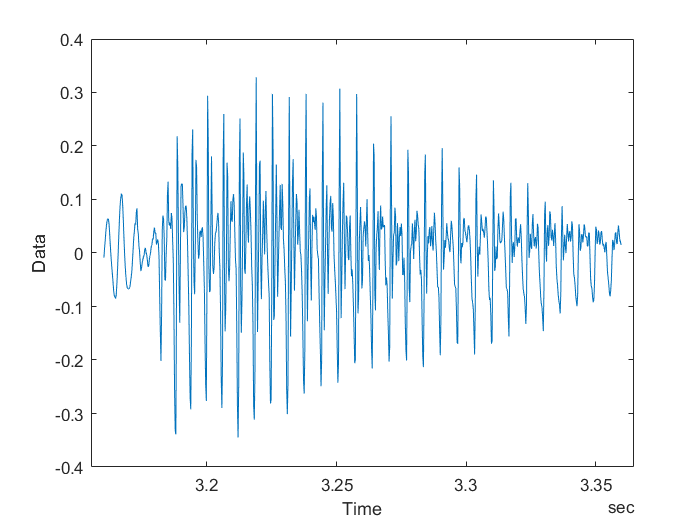

% Extract the word
femaleWord = femaleSpeech(femaleSpeech.Time > seconds(3.16) & ...
    femaleSpeech.Time < seconds(3.36),:);

% If you would like to hear this sound, uncomment the following line
% sound(femaleWord.Data,femaleSampleRate)

% Plot the waveform
plot(femaleWord.Time,femaleWord.Data)
xlabel("Time")
ylabel("Data")

## Examine frequency spectrum

Use the function `periodogram` to see the frequency spectrum. Notice that we're plotting the raw values and *not* the values in decibels. This will make it easier to find peaks. For more examples, see the reading "Examples of summary statistics as features".

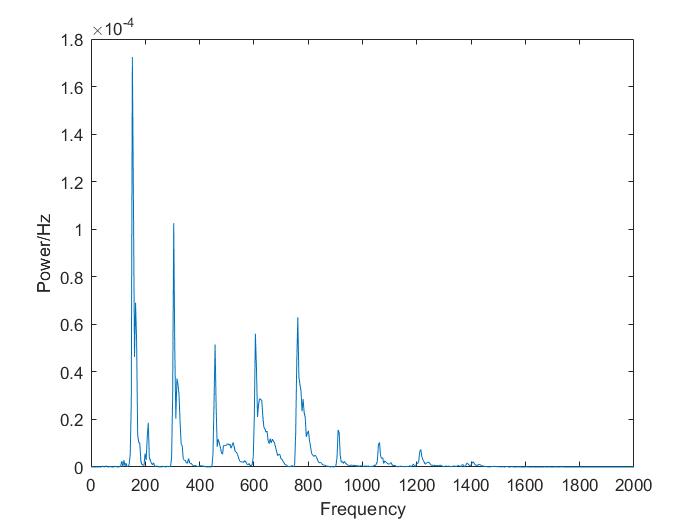

[femaleSpectrum,femaleFrequencies] = periodogram(femaleWord.Data, ...
    [],[],femaleSampleRate);

plot(femaleFrequencies,femaleSpectrum)
xlabel("Frequency")
ylabel("Power/Hz")

## Find peaks in the signal

The "Find Local Extrema" Live Editor Task is a helpful tool for finding peaks in signals. It produces a logical variable `maxIndices` that is the same length as the signal. Values marked as 1 in `maxIndices` are the location of the peaks

Try playing around with values for "Min. prominence" and "Min. separation" to only identify the harmonic peaks.

In the video, the values demonstrated were `1e-5` for min. prominence and 100 Hz for min. separation.  

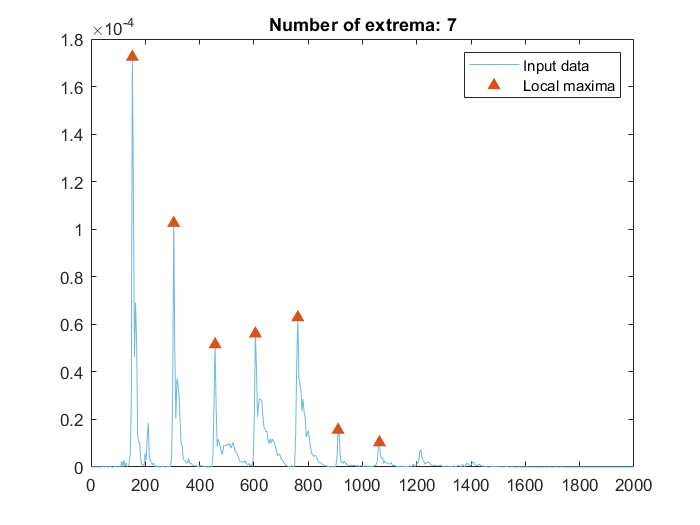

% Find local maxima
maxIndices = islocalmax(femaleSpectrum,'MinProminence',1e-05,...
    'MinSeparation',100,'SamplePoints',femaleFrequencies);

% Visualize results
clf
plot(femaleFrequencies,femaleSpectrum,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on

% Plot local maxima
plot(femaleFrequencies(maxIndices),femaleSpectrum(maxIndices),'^',...
    'Color',[217 83 25]/255,'MarkerFaceColor',[217 83 25]/255,...
    'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices))])
hold off
legend

## Calculate F0 for word

Once the peaks have been identified you can calculate the estimate for the fundamental frequency ($F_0$) by finding the average spacing between peaks.

% Find the spacing between peaks
peakDifferences = diff(femaleFrequencies(maxIndices))

peakDifferences =   152.3438
  152.3438
  148.4375
  156.2500
  148.4375
  152.3438



% Calculate the average
F0 = mean(peakDifferences)

F0 = 151.6927

So the $F_0$ value for this sound is ~152 Hz.

## Try process on Male Speech

Try repeating the process with a sample from the male speech. The parameters that worked for the female speech sample may not work for the male speech sample.

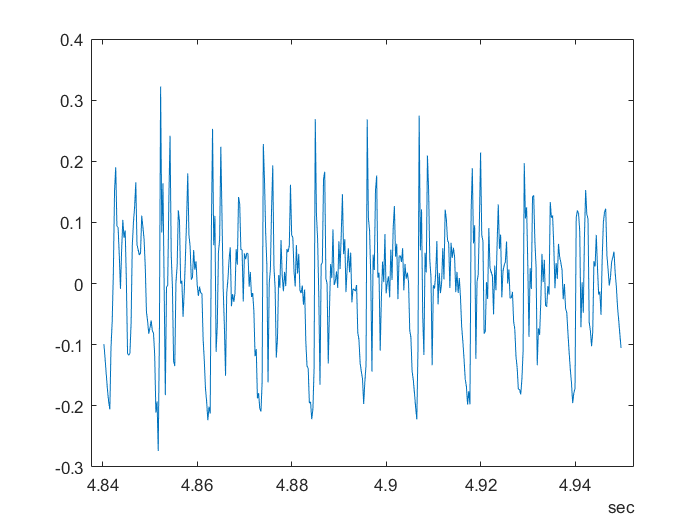

% Extract the male sample.
maleWord = maleSpeech(maleSpeech.Time > seconds(4.84) & ...
    maleSpeech.Time < seconds(4.95),:);
plot(maleWord.Time,maleWord.Data)


% PLot the waveform. The is the vowel sound /ɛ/ from the word "men"
[maleSpectrum,maleFrequencies] = periodogram(maleWord.Data, ...
    [],[],maleSampleRate);

% Uncomment the following line to play the sound
% sound(maleWord.Data,maleSampleRate)

Now try finding peaks with another Live Editor Task. In the video, the values demonstrated were `1e-5` for min. prominence and 60 Hz for min. separation.  

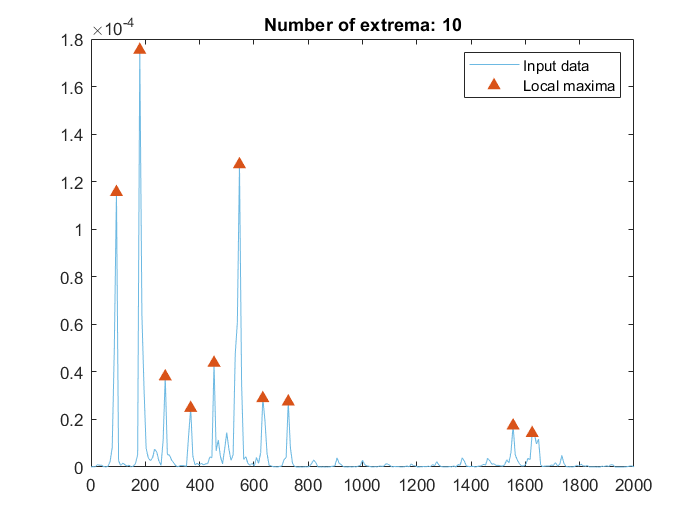

% Find local maxima
maxIndices2 = islocalmax(maleSpectrum,'MinProminence',1e-05,'MinSeparation',60,...
    'MaxNumExtrema',1025,'SamplePoints',maleFrequencies);

% Visualize results
clf
plot(maleFrequencies,maleSpectrum,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on

% Plot local maxima
plot(maleFrequencies(maxIndices2),maleSpectrum(maxIndices2),'^',...
    'Color',[217 83 25]/255,'MarkerFaceColor',[217 83 25]/255,...
    'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices2))])
hold off
legend

Notice that 8 peaks are marked below 800 Hz and 2 peaks are marked above 1500 Hz. This jump creates a very large value in the variable `peakDifferences`, which would bias the mean.

peakDifferences = diff(maleFrequencies(maxIndices2))

peakDifferences =    85.9375
   93.7500
   93.7500
   85.9375
   93.7500
   85.9375
   93.7500
  828.1250
   70.3125


Therefore, it's better to use a statistic that is less susceptible to outliers like the median.

F0 = median(peakDifferences)

F0 = 93.7500

## Calculate F0 for whole waveform

You can use the `retime` function to split up the signal into multiple "windows" and calculate a pitch estimate for each piece.

Instead of referencing a summary statistic like the mean, you can reference any function by preceding the name with the "@" symbol. At the bottom of this script is a function named `estimateF0` that can be used for this purpose.

% Choose a window length
windowLengthms = 100;

% Call retime and reference the custom function estimateF0
maleF0s = retime(maleSpeech,"regular",@estimateF0, ...
    "TimeStep",milliseconds(windowLengthms))

maleF0s = 200×1 timetable
     Time       Data 
    _______    ______

    0 sec         NaN
    0.1 sec       125
    0.2 sec    167.97
    0.3 sec    109.38
    0.4 sec    101.56
    0.5 sec    101.56
    0.6 sec    97.656
    0.7 sec    101.56
    0.8 sec     93.75
    0.9 sec     93.75
    1 sec       93.75
    1.1 sec    85.938
    1.2 sec       NaN
    1.3 sec    101.56
    1.4 sec    117.19
    1.5 sec    195.31


Notice the output is a timetable with a pitch estimate for each window.

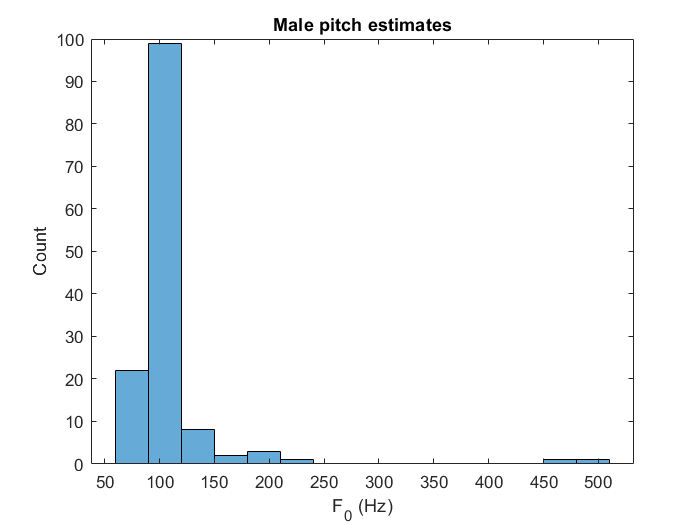

% Plot the result with a histogram
histogram(maleF0s.Data)
title("Male pitch estimates")
xlabel("F_0 (Hz)" )
ylabel("Count")

The histogram shows that there are some values above 450 Hz. These are probably not valid pitch estimates, so they can be treated as outliers and removed

% Remove missing valus and outliers
maleF0s = rmmissing(maleF0s,"DataVariables","Data");
maleF0s = rmoutliers(maleF0s,"median","DataVariables","Data");

Now repeat the same process for the female speech data.

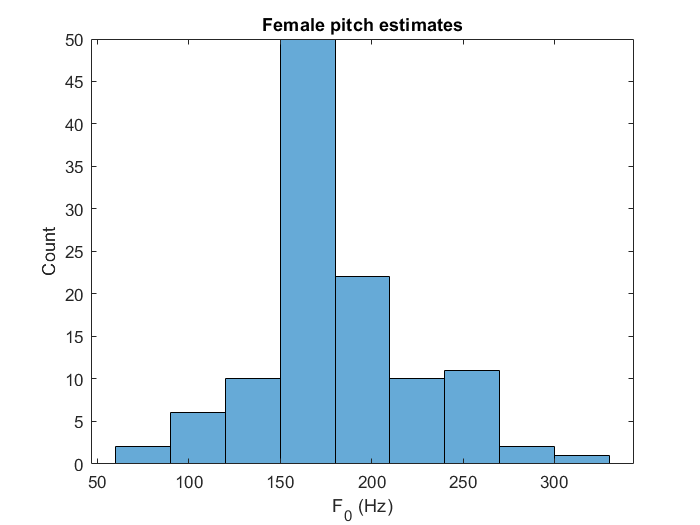

femaleF0s = retime(femaleSpeech,"regular",@estimateF0, ...
    "TimeStep",milliseconds(windowLengthms));

% Plot histogram
histogram(femaleF0s.Data)
xlabel("F_0 (Hz)")
ylabel("Count")
title("Female pitch estimates")


% Remove missing values and outliers
femaleF0s = rmmissing(femaleF0s,"DataVariables","Data");
femaleF0s = rmoutliers(femaleF0s,"median","DataVariables","Data");

Finally, you can plot both histograms together to compare the distributions

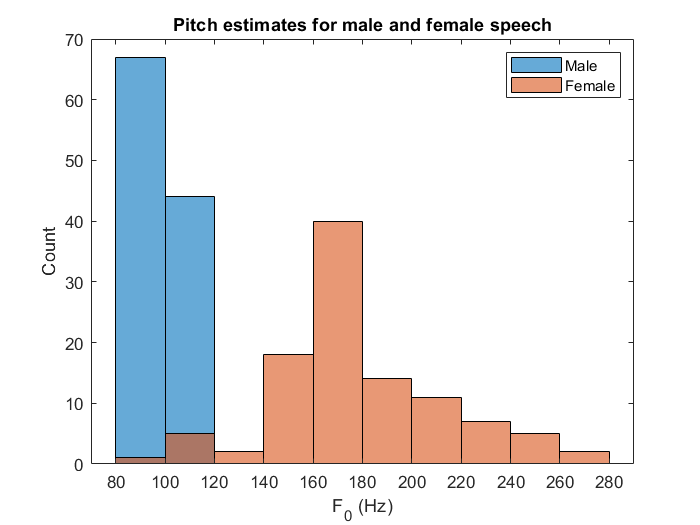

histogram(maleF0s.Data,"BinWidth",20)
hold on
histogram(femaleF0s.Data,"BinWidth",20)
hold off
legend("Male","Female")
xlabel("F_0 (Hz)")
ylabel("Count")
title("Pitch estimates for male and female speech")

## Calculate ANOVA

To evaluate the usefulness of the pitch as a feature, you can perform a 1-way ANOVA.

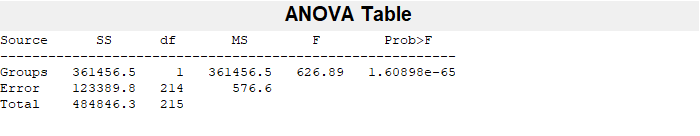

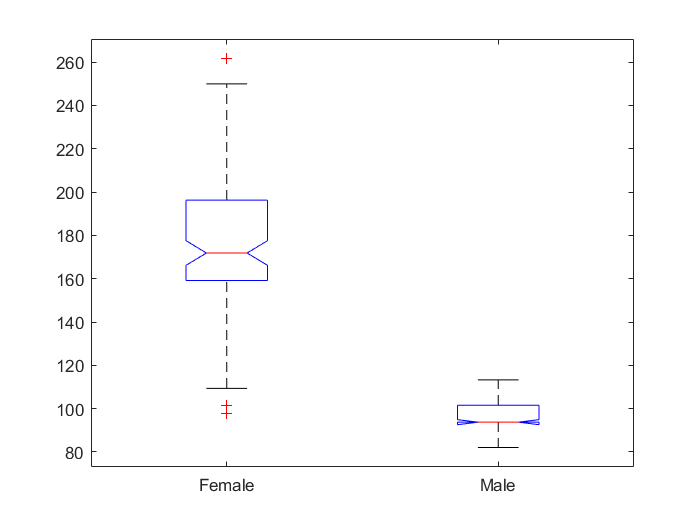

pValue = 1.6090e-65

% Combine pitch estimates together
X = [femaleF0s.Data; maleF0s.Data];

% Create a label variable with "Female" or "Male" labels
g = [repelem("Female",height(femaleF0s),1); ...
    repelem("Male",height(maleF0s),1)];

% Perform the 1 way ANOVA
pValue = anova1(X,g)

Notice the p-value is very small, meaning it is highly significant. Therefore, this measure of pitch is a good feature telling apart these particular male and female speakers. To see if holds for *any* speaker, we would need to collect more data.

## Calc F0 function

This is the helper function used with `retime` to calculate the pitch for different windows. Note that the output `F0` is initially set to `NaN`, but it's overwritten if there's data in the input signal. This is necessary for the function `retime`, which requires functions that don't return an error if the input is empty.

function F0 = estimateF0(data)
% function ESTIMATEF0 - calculate pitch for a signal

% Calculate F0 is the input is non-empty. This is necessary to use with
% retime (it doesn't allow you to reference functions that return an error
% with an empty input. So we start with an F0 of NaN and update the value
% if the input is non-empty.
F0 = NaN;
if ~isempty(data)

    % Calculate spectrum with periodogram.
    sampleRate = 4000;
    [spectrum,frequencies] = periodogram(data,[],[],sampleRate);

    % Find local maxima using the auto-generated code from the Live Editor
    % Task.
    maxIndices = islocalmax(spectrum,'MinProminence',1e-5, ...
        'MinSeparation',60,'SamplePoints',frequencies);

    % Calc F0 from inter-peak frequency
    peakDifferences = diff(frequencies(maxIndices));
    F0 = median(peakDifferences);

end
end

## Download Sound Files function

This is the helper function downloads and unzips the required sound files from mathworks.com. The files are stored on your computer's default temporary directory.

function netFolder = downloadSoundFiles
url = 'http://ssd.mathworks.com/supportfiles/audio/CocktailPartySourceSeparation.zip';
downloadNetFolder = tempdir;

netFolder = fullfile(downloadNetFolder,'CocktailPartySourceSeparation');

if ~exist(netFolder,'dir')
    unzip(url,downloadNetFolder)
end
end